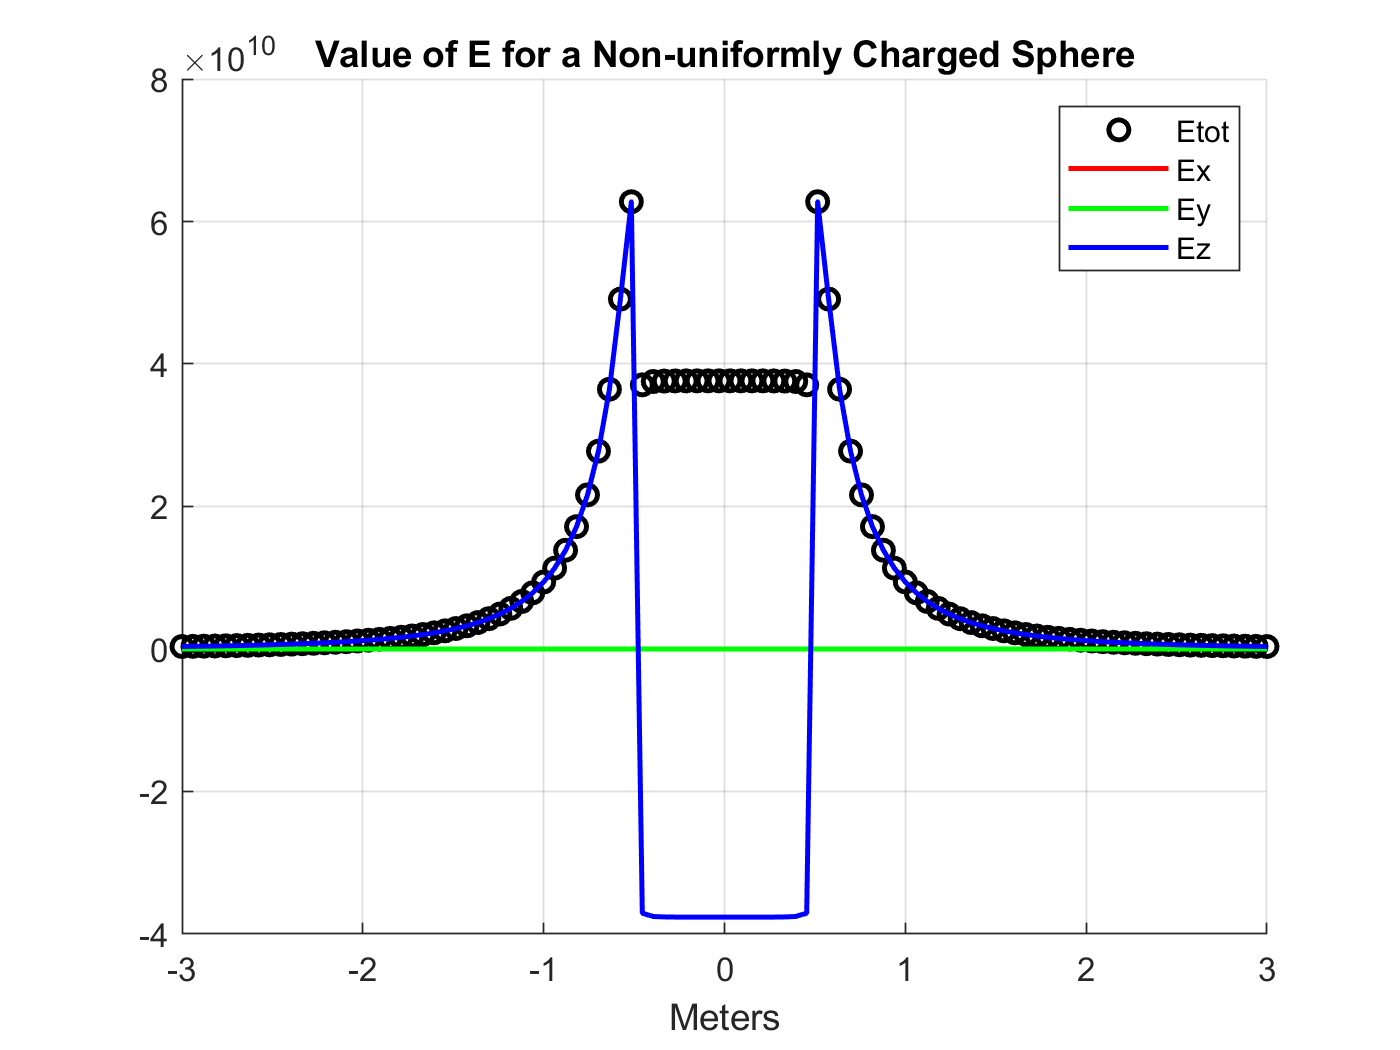

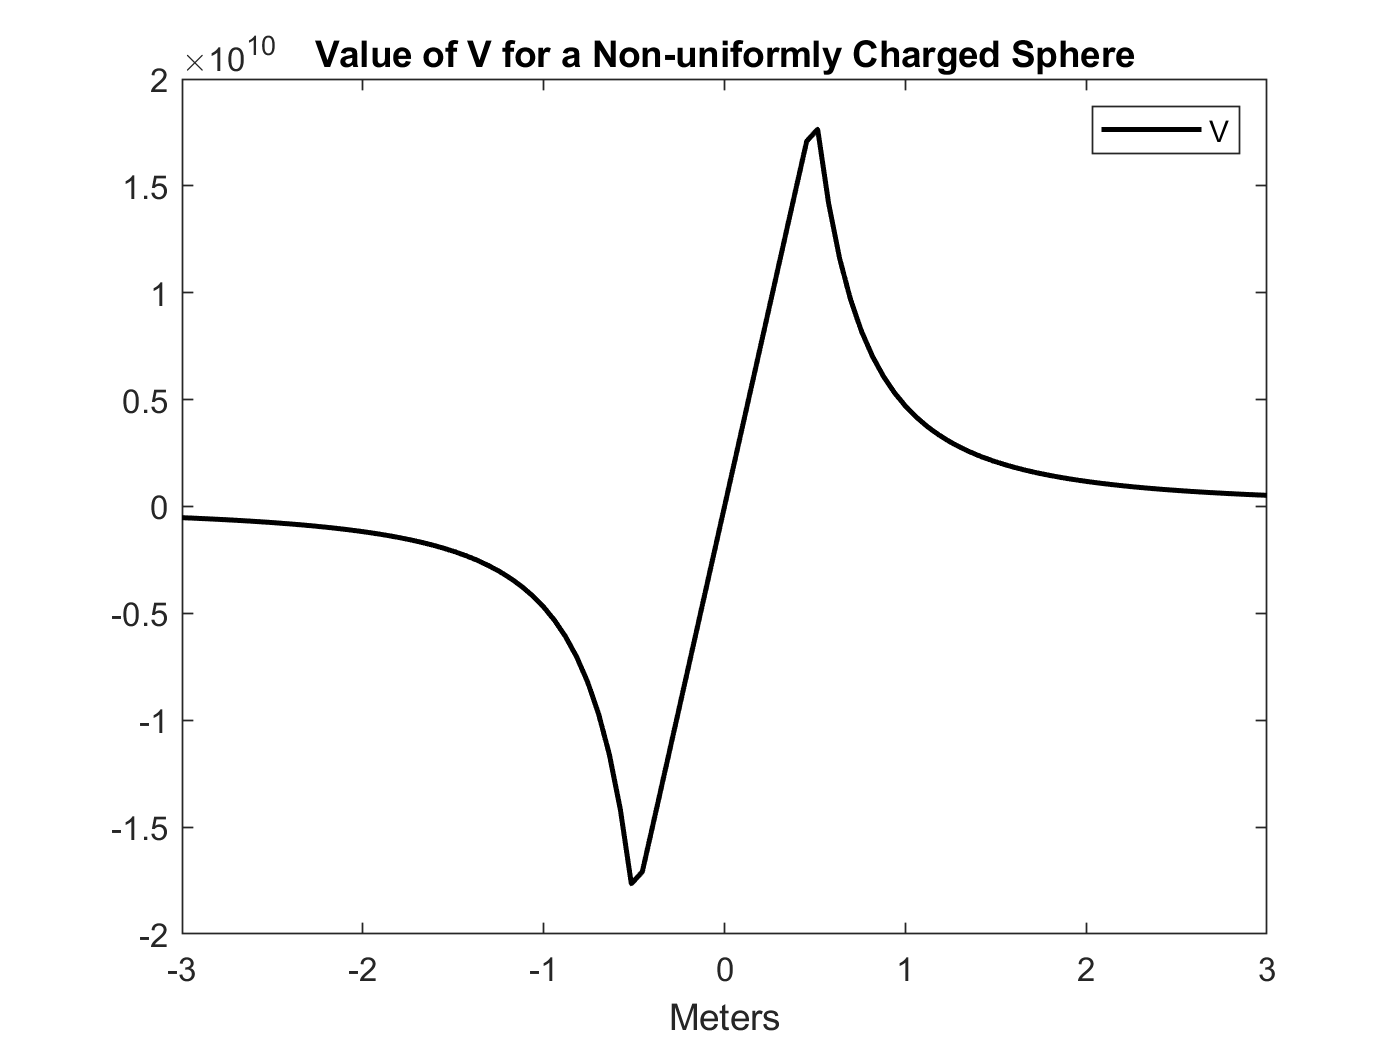

% Author: Shi Jie (Barney) Wei
% Date: 03/11/19

% PREP: sphere_of_charge_nonuniform
a = 0.01;
rhos = -5e-9;
x = 0;
y = 0;
z = 0.02;
N = 500;
%[Etot, Ex, Ey, Ez, V] = sphereofcharge_uniform(a,rhos,x,y,z,N);

% 1.1) Uniformly Charged Spherical Shell
a = 0.5;
rhos = 2e-6;
y1 = -3;
y2 = 3;
N = 100;
%plot_sphere_of_charge_uniform_y(a,rhos,y1,y2,N);

% 1.2) Non-uniformly Charged Spherical Shell
a = 0.5;
rhos = 1;
z1 = -3;
z2 = 3;
N = 100;
plot_sphere_of_charge_nonuniform_z(a,rhos,z1,z2,N);

function [Etot,Ex,Ey,Ez]=sphereofcharge(a,rhos,x,y,z,N)
% PREP: sphere_of_charge
    epsilon=8.854e-12;
    dtheta = pi/N;
    dphi = 2*pi/N;
    theta = linspace(0, pi, N+1);
    phi = linspace(dphi, 2*pi, N);
    
    % Integrate surface using nested for loop
    for e=1:length(phi)
        for m=1:length(theta)
            dInt1(m) = rhos*sin(theta(m))*dtheta*dphi;
        end
        dInt2(e) = sum(dInt1);
    end
    
    % Do the "integration" by summing up the differential pieces that result from
    % each value of zprime.
    round_num = 6;
    Ex=round(sum(((a^2)/(4*pi*epsilon*(x^2))) .* dInt2), round_num);
    Ey=round(sum(((a^2)/(4*pi*epsilon*(y^2))) .* dInt2), round_num);
    Ez=round(sum(((a^2)/(4*pi*epsilon*(z^2))) .* dInt2), round_num);
    if ((x < a) && (y < a) && (z < a))
        Ex = 0;
        Ey = 0;
        Ez = 0;
    end
    if (x == 0)
        Ex = 0;
    end
    if (y == 0)
        Ey = 0;
    end
    if (z == 0)
        Ez = 0;
    end
    Etot=(Ex^2+Ey^2+Ez^2)^0.5;
end


% PREP: sphere_of_charge_uniform
function [Etot,Ex,Ey,Ez,V]=sphereofcharge_uniform(a,rhos,x,y,z,N)
    epsilon=8.854e-12;
    dtheta = pi/N;
    dphi = 2*pi/N;
    theta = linspace(0, pi, N+1);
    phi = linspace(dphi, 2*pi, N);
    % Integrate surface using nested for loop
    for e=1:length(phi)
        for m=1:length(theta)
            x_sph = x - a*sin(theta(m))*cos(phi(e));
            y_sph = y - a*sin(theta(m))*sin(phi(e));
            z_sph = z - a*cos(theta(m));
            r_sph = (x_sph^2 + y_sph^2 + z_sph^2)^(1/2);
            ratio_sph_E = ((a^2)*rhos*sin(theta(m))/(r_sph^3))*dtheta*dphi;
            ratio_sph_V = ((a^2)*rhos*sin(theta(m))/(r_sph))*dtheta*dphi;
            dInt1x(m) = ratio_sph_E * x_sph;
            dInt1y(m) = ratio_sph_E * y_sph;
            dInt1z(m) = ratio_sph_E * z_sph;
            dInt1V(m) = ratio_sph_V;
        end
        dInt2x(e) = sum(dInt1x);
        dInt2y(e) = sum(dInt1y);
        dInt2z(e) = sum(dInt1z);
        dInt2V(e) = sum(dInt1V);
    end
    % Do the "integration" by summing up the differential pieces
    round_num = 6;
    Ex = round(sum((1/(4*pi*epsilon)) .* dInt2x), round_num);
    Ey = round(sum((1/(4*pi*epsilon)) .* dInt2y), round_num);
    Ez = round(sum((1/(4*pi*epsilon)) .* dInt2z), round_num);
    Etot = (Ex^2+Ey^2+Ez^2)^0.5;
    V = round(sum((1/(4*pi*epsilon)) .* dInt2V), round_num);
end

% 1.1 plot_sphere_of_charge_uniform
function plot_sphere_of_charge_uniform_y(a,rhos,y1,y2,N)
    y_vec = linspace(y1, y2, N);
    for e=1:length(y_vec)
        [Etot(e), ~, ~, ~, V(e)] = sphereofcharge_uniform(a,rhos,0,y_vec(e),0,N);
        [Etot_theory(e), V_theory(e)] = sphere_of_charge_y_theory(a, rhos, y_vec(e));
    end
    hold on;
    grid on;
    plot(y_vec, Etot, 'ro', 'LineWidth', 1.5);
    plot(y_vec, V, 'go', 'LineWidth', 1.5);
    plot(y_vec, Etot_theory, 'k-', 'LineWidth', 1.5);
    plot(y_vec, V_theory, 'b-', 'LineWidth', 1.5);
    legend('Etot', 'V', 'E_theory', 'V_theory');
    xlabel('Meters');
    title('Value of E and V for a Uniformly Charged Sphere');
end

% 1.1.2 sphere_of_charge_y_theory
function [E_theory,V_theory]=sphere_of_charge_y_theory(a,rhos,y)
    epsilon=8.854e-12;
    if (abs(y) < a)
        E_theory = 0;
        V_theory = (rhos*a) / epsilon;
    else
        E_theory = (rhos*a^2) / (epsilon*y^2);
        V_theory = (rhos*a^2) / (epsilon*abs(y));
    end
end

% 1.2 plot_sphere_of_charge_nonuniform
function plot_sphere_of_charge_nonuniform_z(a,rhos,z1,z2,N)
    z_vec = linspace(z1, z2, N);
    for e=1:length(z_vec)
        [Etot(e), Ex(e), Ey(e), Ez(e), V(e)] = sphereofcharge_nonuniform(a,rhos,0,0,z_vec(e),N);
    end
    hold on;
    grid on;
    plot(z_vec, Etot, 'ko', 'LineWidth', 1.5);
    plot(z_vec, Ex, 'r-', 'LineWidth', 1.5);
    plot(z_vec, Ey, 'g-', 'LineWidth', 1.5);
    plot(z_vec, Ez, 'b-', 'LineWidth', 1.5);
    legend('Etot', 'Ex', 'Ey', 'Ez');
    xlabel('Meters');
    title('Value of E for a Non-uniformly Charged Sphere');
    figure;
    plot(z_vec, V, 'k-', 'LineWidth', 1.5);
    legend('V');
    xlabel('Meters');
    title('Value of V for a Non-uniformly Charged Sphere');
end
% 1.2.1 sphereofcharge_nonuniform
function [Etot,Ex,Ey,Ez,V]=sphereofcharge_nonuniform(a,rhos,x,y,z,N)
    epsilon=8.854e-12;
    dtheta = pi/N;
    dphi = 2*pi/N;
    theta = linspace(0, pi, N+1);
    phi = linspace(dphi, 2*pi, N);
    rhos_vec = rhos.*cos(linspace(0, pi, length(theta)));
    % Integrate surface using nested for loop
    for e=1:length(phi)
        for m=1:length(theta)
            x_sph = x - a*sin(theta(m))*cos(phi(e));
            y_sph = y - a*sin(theta(m))*sin(phi(e));
            z_sph = z - a*cos(theta(m));
            r_sph = (x_sph^2 + y_sph^2 + z_sph^2)^(1/2);
            ratio_sph_E = ((a^2)*rhos_vec(m)*sin(theta(m))/(r_sph^3))*dtheta*dphi;
            ratio_sph_V = ((a^2)*rhos_vec(m)*sin(theta(m))/(r_sph))*dtheta*dphi;
            dInt1x(m) = ratio_sph_E * x_sph;
            dInt1y(m) = ratio_sph_E * y_sph;
            dInt1z(m) = ratio_sph_E * z_sph;
            dInt1V(m) = ratio_sph_V;
        end
        dInt2x(e) = sum(dInt1x);
        dInt2y(e) = sum(dInt1y);
        dInt2z(e) = sum(dInt1z);
        dInt2V(e) = sum(dInt1V);
    end
    % Do the "integration" by summing up the differential pieces
    round_num = 6;
    Ex = round(sum((1/(4*pi*epsilon)) .* dInt2x), round_num);
    Ey = round(sum((1/(4*pi*epsilon)) .* dInt2y), round_num);
    Ez = round(sum((1/(4*pi*epsilon)) .* dInt2z), round_num);
    Etot = (Ex^2+Ey^2+Ez^2)^0.5;
    V = round(sum((1/(4*pi*epsilon)) .* dInt2V), round_num);
end